close all
clear

tr= stlread('part1.stl')

tr =   triangulation のプロパティ:

              Points: [4145×3 double]
    ConnectivityList: [8286×3 double]



p=tr.Points

p =    -3.5000   58.6240  -80.2178
  -17.5000   59.8250  -78.2696
   -2.5000   58.0842  -79.2224
   -6.7559   58.0256  -77.8561
   -2.5000   57.4600  -77.9983
   -6.7559   57.2936  -76.7206
   -2.5000   56.6929  -76.8576
   -6.7559   56.4094  -75.7001
   -2.5000   56.2496  -76.3377
   -2.5000   55.8481  -75.9463



j=1

j = 1

pj=p(j,:)

pj =    -3.5000   58.6240  -80.2178



figure
scatter3(pj(:,1),pj(:,2),pj(:,3),'filled')
axis('equal')
xlabel('X')
ylabel('Y')
zlabel('Z')

t=pi/3

t = 1.0472


rz=[cos(t), -sin(t),0;
   sin(t),cos(t),0 ;
   0,0,1]

rz =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000



rx=[1,0,0;
    0,cos(t),-sin(t);
    0,sin(t),cos(t)]

rx =     1.0000         0         0
         0    0.5000   -0.8660
         0    0.8660    0.5000



ry=[cos(t),0,-sin(t);
    0,1,0;
    sin(t),0,cos(t)]

ry =     0.5000         0   -0.8660
         0    1.0000         0
    0.8660         0    0.5000



rp=rz*(pj.')

rp =   -52.5199
   26.2809
  -80.2178



np=zeros(size(p))

np =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



i=1

i = 1

np(i,1)=rp(1)

np =   -52.5199         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


np(i,2)=rp(2)

np =   -52.5199   26.2809         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


np(i,3)=rp(3)

np =   -52.5199   26.2809  -80.2178
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


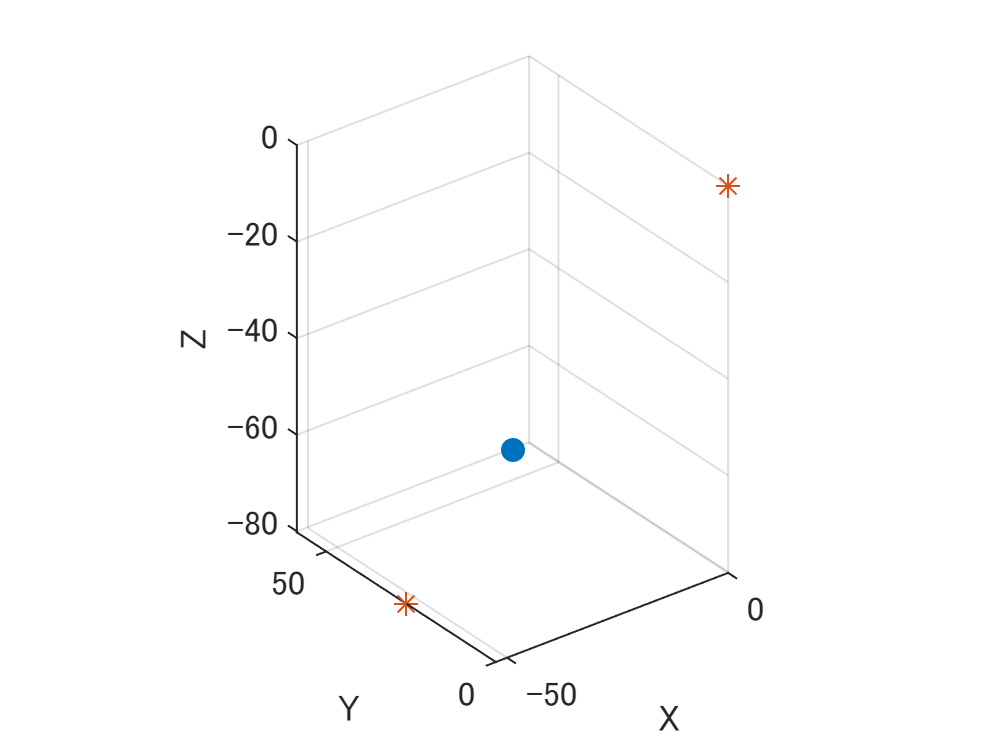


hold on
scatter3(np(:,1),np(:,2),np(:,3),'*')